clear all
ac_M0
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:21)=0.0;
for t=1:21
    varname=genvarname(['media_' int2str((t-1)*100)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end


f=plot(0.05*[0:100:2000]/24,glucose(:),'LineWidth',2,'Color','black')

f =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2083 0.4167 0.6250 0.8333 1.0417 1.2500 1.4583 1.6667 1.8750 2.0833 2.2917 2.5000 2.7083 2.9167 3.1250 3.3333 3.5417 3.7500 3.9583 4.1667]
              YData: [0 8.0618e-04 6.2086e-04 4.2642e-04 2.6949e-04 1.6183e-04 9.5259e-05 5.5749e-05 3.2589e-05 1.9038e-05 1.1113e-05 6.4836e-06 3.7810e-06 2.2042e-06 1.2847e-06 7.4868e-07 4.3622e-07 2.5414e-07 1.4805e-07 8.6240e-08 5.0233e-08]

  Show all properties


%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 5]
             YLim: [0 1.0000e-03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1614 0.1703 0.7436 0.7394]
            Units: 'normalized'

  Show all properties


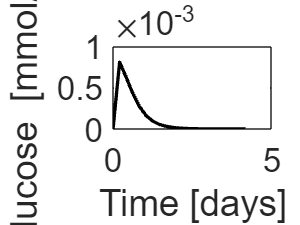

hold on

ac_M16
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:21)=0.0;
for t=1:21
    varname=genvarname(['media_' int2str((t-1)*100)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end

plot(0.05*[0:100:2000]/24,glucose(:),'LineWidth',2,'Color','black')
%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 5]
             YLim: [0 0.0015]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1614 0.1703 0.7436 0.7394]
            Units: 'normalized'

  Show all properties


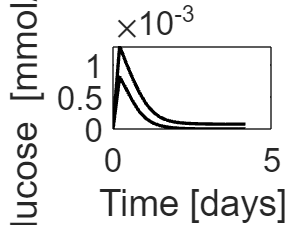

hold on

saveas(gcf,['acetate.png'])